# **demo13 of Im2mesh package**

demo13 - How to use Gmsh as mesh generator in Im2mesh package

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com

## Note

I suggest familiarizing yourself with Im2mesh_GUI before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package.

Im2mesh_GUI: [https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh)

If you are using Im2mesh package in MATLAB,  you need to install MATLAB Image Processing Toolbox and Mapping Toolbox because Im2mesh package use a few functions in these toolboxes.

**Before starting, you need to download Gmsh (**[**https://gmsh.info**](https://gmsh.info)**  and un-zip.**

## Setup

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size.

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

We add the folder 'mesh2d-master' and 'printGeo' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))
addpath(genpath('printGeo'))

We specify the location of gmesh.exe

path_to_gmsh = 'C:\Users\Jason\gmsh-4.13.1-Windows64\gmsh.exe';

## Get boundries from image

We have demostrate how to do this in demo04.

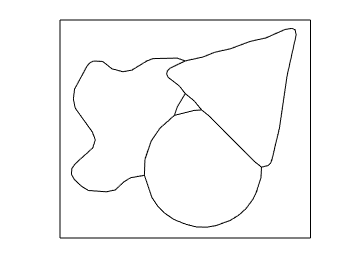

im = imread("Shape.tif");
if size(im,3) == 3;  im = rgb2gray( im ); end

% image to polygon boundary
boundsRaw = im2Bounds( im );
boundsCtrlP = getCtrlPnts( boundsRaw, false, size(im) );

% smooth boundary
boundsSmooth = smoothBounds( boundsCtrlP, 0.5, -0.5, 100, 0, 0 );

% simplify polygon boundary
boundsSimplified = simplifyBounds( boundsSmooth, 0.3, 0 );
boundsSimplified = delZeroAreaPoly( boundsSimplified );

% clear up redundant vertices
% only control points and turning points will remain
boundsClear = getCtrlPnts( boundsSimplified, false );
boundsClear = simplifyBounds( boundsClear, 0 );

plotBounds( boundsClear );

## Phase selection before meshing

Suppose we don't need the background.

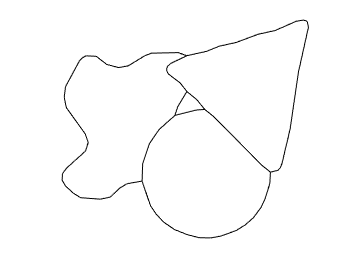

select_phase = [2 3 4];
boundsClear = boundsClear( select_phase );
plotBounds( boundsClear );

## Obtain loops from polygonal boundaries

Gmsh use loops to define suface. I developed some functions to do that.

% prepare data
[ poly_node, poly_edge ] = getPolyNodeEdge( boundsClear );
% organize cell array poly_node, poly_edge into array node, edge.
[ node, edge, part ] = regroup( poly_node, poly_edge );

% Delaunay triangulation in 2D using subfunction deltri1
[vertex,~,tria,label] = deltri1( node, edge, node, edge, part );

% convert to loops
num_phase = length( unique(label) );
phaseLoops = cell( 1, num_phase );
for i = 1: num_phase
	triaP = tria( label==i, : );
	% triangular mesh of one phase to surface loop cell
	phaseLoops{i} = triaPha2loop(triaP, vertex, edge);
end

## Print geo file for Gmsh

geo file is the input file for Gmsh. We use function printGeo to print a geo file 'gmshTemp.geo'. 

% rename variables to consistent with gmsh
point = vertex;
line = edge;
C = phaseLoops;

% setup parameters
opt.sizeMin = 0.1;
opt.sizeMax = 50;
opt.algthm = 6;
opt.recombAll = 0;
opt.recombAlgthm = 3;
opt.eleOrder = 1;

path_to_geo = 'gmshTemp.geo';
printGeo( C, point, line, opt, path_to_geo );

## Generate mesh via Gmsh

We use the following command to send the geo file to Gmsh. Gmsh will generate a m file 'gmshTemp.m'. When we run the m file, we will see a struct variable 'msh' in the work space of 

path_to_m = 'gmshTemp.m';
v = 3;  % verbosity

str=sprintf('"%s" "%s" -o "%s" -v %i -save', ... 
			path_to_gmsh, path_to_geo, path_to_m, v );
system(str);

When we run the m file, we will see a struct variable 'msh' in the workspace of MATLAB.

run(path_to_m)
msh

msh = struct with fields:
        nbNod: 276
          POS: [276×3 double]
          MAX: [87.2400 77.4400 0]
          MIN: [4.6900 4.4500 0]
    TRIANGLES: [486×4 double]


## Plot mesh

Before ploting the mesh, we need to do some pre-process to the mesh data. 

vert = msh.POS(:,1:2);
ele = msh.TRIANGLES(:,1:end-1);
tnum = msh.TRIANGLES(:,end);

% flip for correct signs
area = triarea( vert, ele );
ele(area<0.,:) = ele( area<0., [1,3,2] );

Now we can plot the mesh

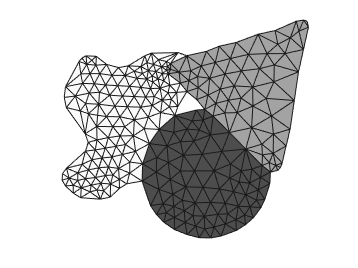

plotMeshes( vert, ele, tnum )

## Comments

If the mesh is quadratic trangular, the pre-processing is slightly different.

After we got the mesh, we can use the command in demo03 to export it.

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo